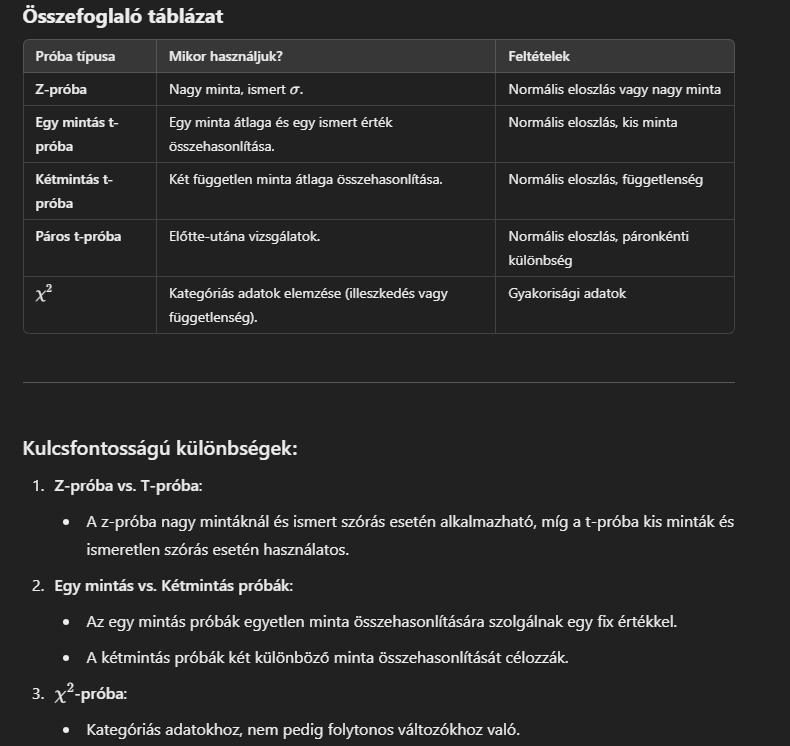

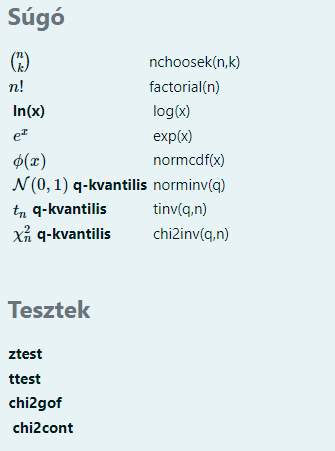

 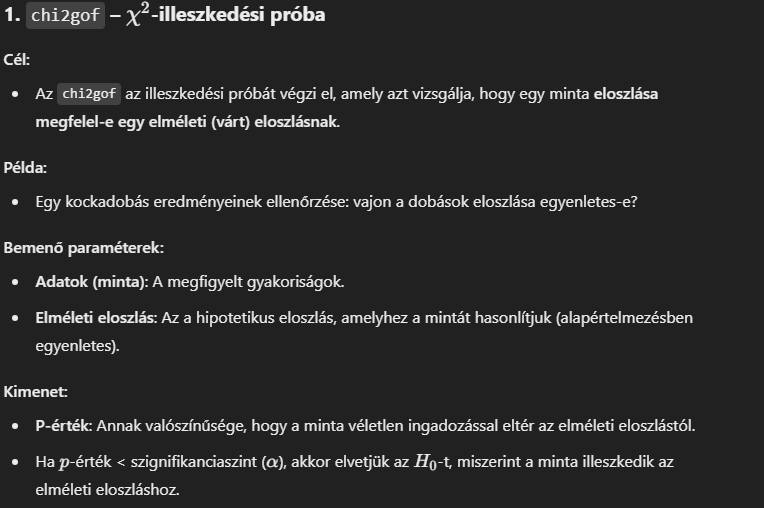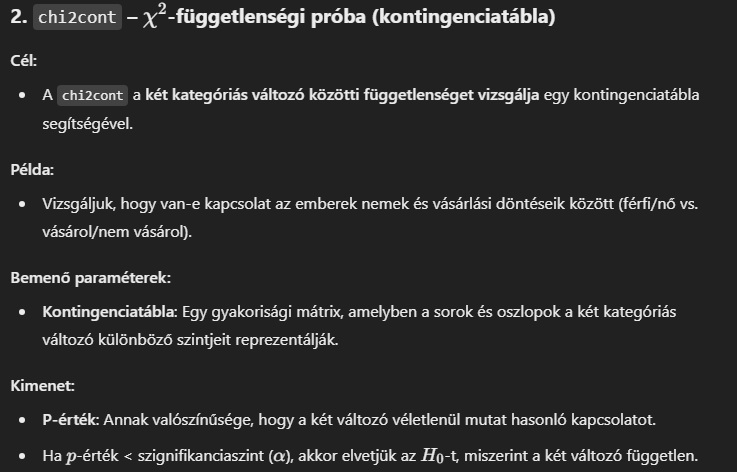

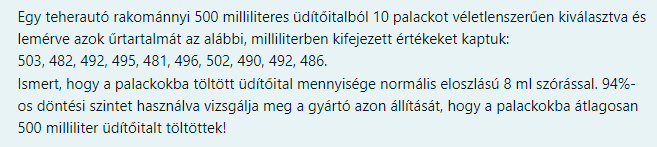

Ezt a problémát egy **egymintás z-teszttel** oldhatjuk meg, mivel a populáció ***szórását ***σ (sigma) = 7 ***ismertnek tekintjük, és a minta normális eloszlást követ.***

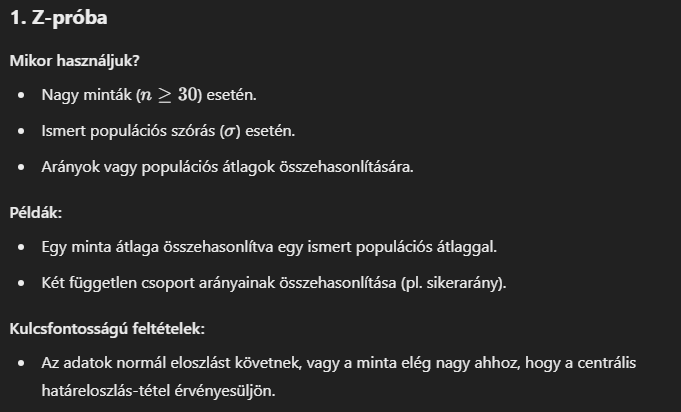

**Nullhipotézis** (H0) = 500 - Az üdítőital átlagos töltött mennyisége 500 ml.

**Alternatív hipotézis** (H1) ≠ Az üdítőital átlagos töltött mennyisége nem 500 m

% Adatok és ismert értékek
data = [499, 504, 499, 489, 491, 499, 486, 496, 483, 491];  % Mintavétel
n = length(data);        % Minta elemszáma
sigma = 7;               % Ismert populáció szórás
mu_0 = 500;              % Nullhipotézisbeli átlag
alpha = 0.02;            % Szignifikanciaszint (1 - 98%)


ans = 0.0774

x_bar = mean(data); % 1. Mintaátlag 
z = (x_bar - mu_0) / (sigma / sqrt(n)); %Próbastatisztika értéke
z_crit = norminv(1 - alpha / 2); % Kritikus értékek meghatározása (kétoldali teszt)

% 4. Döntés
if abs(z) > z_crit
    decision = 1;  % Nullhipotézis elutasítása
else
    decision = 0;  % Nullhipotézis elfogadása
end

% Eredmények kiírása
disp('Próbastatisztika értéke (z):');

Próbastatisztika értéke (z):


disp(z);

   -2.8460



disp('Elfogadási tartomány határai (kritikus értékek):');

Elfogadási tartomány határai (kritikus értékek):


disp([-z_crit, z_crit]);

   -2.3263    2.3263



disp('Döntés (0=elfogad, 1=elutasít):');

Döntés (0=elfogad, 1=elutasít):


disp(decision);

     1



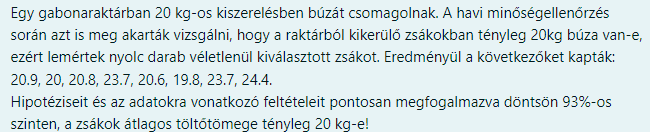

A feladatot egy **egymintás t-teszttel** oldhatjuk meg, mivel a minta ***szórása nem ismert***, ***és a minta elemszáma kicsi*** (n = 8). A t-tesztnél a minta átlagát és a minta szórását használjuk a próba statisztikájának kiszámításához.

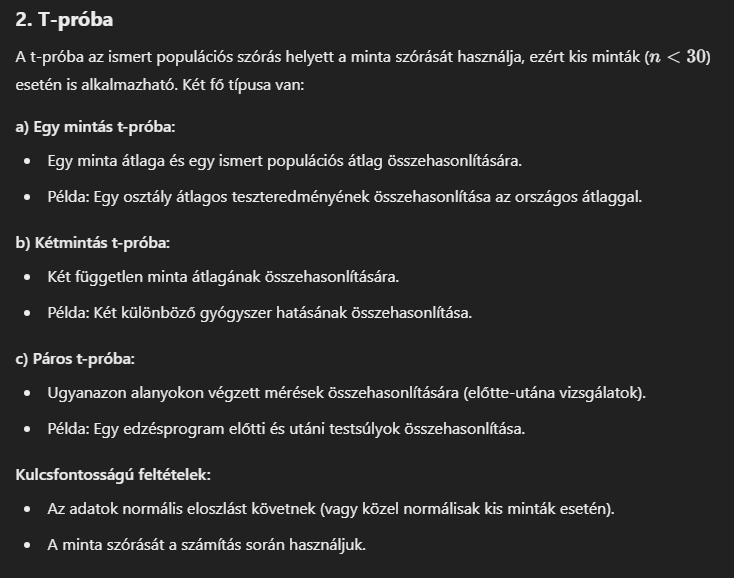

**Nullhipotézis** (H0): Az átlagos töltőtömeg μ=30 kg

**Alternatív hipotézis** (H1): Az átlagos töltőtömeg eltér a 30 kg-tól

% Adatok
data = [32.3, 29.9, 33.2, 30.9, 30.8, 28, 33.5, 32.3];  % Minta
n = length(data);  % Minta elemszáma
mu_0 = 30;  % Nullhipotézis szerinti átlag
alpha = 0.06;  % Szignifikancia szint (94%-os bizalom)
% 1. Minta átlagának és szórásának kiszámítása
x_bar = mean(data);  % Minta átlag
s = std(data);  % Minta szórás

% 2. Próbastatisztika értéke (t-érték)
t_stat = (x_bar - mu_0) / (s / sqrt(n));

% 3. Kritikus értékek meghatározása t-eloszlásból (kétoldali teszt)
t_crit = tinv(1 - alpha / 2, n - 1);  % 7 szabadsági fokkal

% 4. Döntés
if abs(t_stat) > t_crit
    decision = 1;  % Elutasítjuk a nullhipotézist
else
    decision = 0;  % Elfogadjuk a nullhipotézist
end

% Eredmények kiírása
disp('Próbastatisztika értéke (t):');

Próbastatisztika értéke (t):


disp(t_stat);

    2.0953



disp('Kritikus értékek (t_crit):');

Kritikus értékek (t_crit):


disp([-t_crit, t_crit]);

   -2.2409    2.2409



disp('Döntés (0=elfogad, 1=elutasít):');

Döntés (0=elfogad, 1=elutasít):


disp(decision);

     0



Készítsen egy [Matlab](https://elearning.unideb.hu/mod/quiz/view.php?id=386146) függvényt, amely egy n-elemű **x** mintavektor, **m0 **várható érték, **sigma** szórás és **alpha** szignifikancia szint esetén visszaadja a 2-oldai z-próba teszt-statisztikáját (**z**) és az elfogadási tartományát (**ET**):

function [z ET] = z_test(x,m0,sigma,alpha)
    z = (mean(x)-m0) / sigma * sqrt(length(x));
    ET = [-norminv(1-alpha/2) norminv(1-alpha/2)];
end

[z ET] = z_test([5 2 4.4 9 11 7.7],8,3,0.1);
disp(z);

   -1.2111



disp(ET);

   -1.6449    1.6449



Plussz feladat

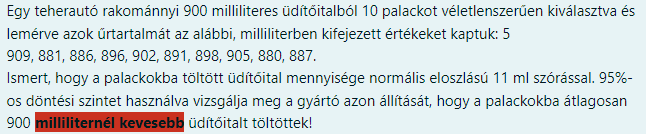

Miért z-próba? A szórás ismert, normális eloszlású minta

**Miért nem kétoldali? **Kétoldali próbát akkor végeznénk, ha azt szeretnénk vizsgálni, hogy az átlag eltér-e 450-től, azaz lehet-e akár kisebb, akár nagyobb is. Itt azonban egyértelműen az a kérdés, hogy az átlag **kisebb-e** a 450 ml-nél, tehát egyoldali próbára van szükség.

**Nullhipotézis (H₀):** Az üdítőital átlagos mennyisége 450 ml, azaz μ=450 ml.

**Alternatív hipotézis (H₁):** Az üdítőital átlagos mennyisége kevesebb, mint 450 ml, azaz μ < 450 ml.

% Adatok
data = [444, 454, 435, 455, 435, 433, 444, 459, 455, 441];
mu0 = 450; % Nullhipotézis szerinti átlag
sigma = 10; % Szórás
n = length(data); % Minta elemszáma
alpha = 0.03; % Szignifikanciaszint

x_bar = mean(data); % Mintaátlag
z = (x_bar - mu0) / (sigma / sqrt(n)); % Próbastatisztika
z_crit = norminv(alpha); % Kritikus érték

% Döntés
if z < z_crit
    decision = 1; % Nullhipotézist elutasítjuk
else
    decision = 0; % Nullhipotézist elfogadjuk
end

% Eredmények kiírása
fprintf('Próbastatisztika értéke: %.3f\n', z);

Próbastatisztika értéke: -1.423


fprintf('Kritikus érték: %.3f\n', z_crit);

Kritikus érték: -1.881


fprintf('Döntés: %d\n', decision);

Döntés: 0
